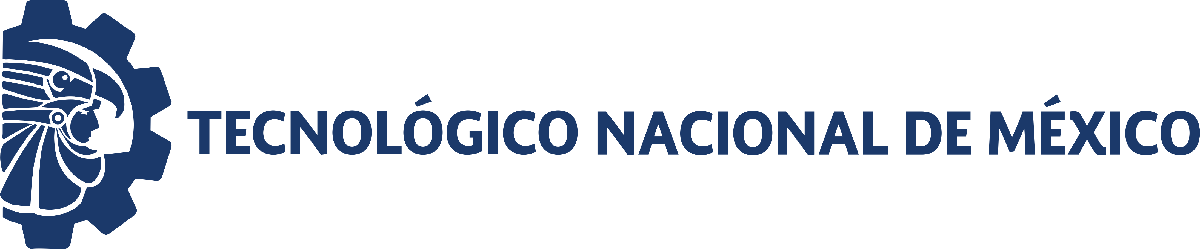                                 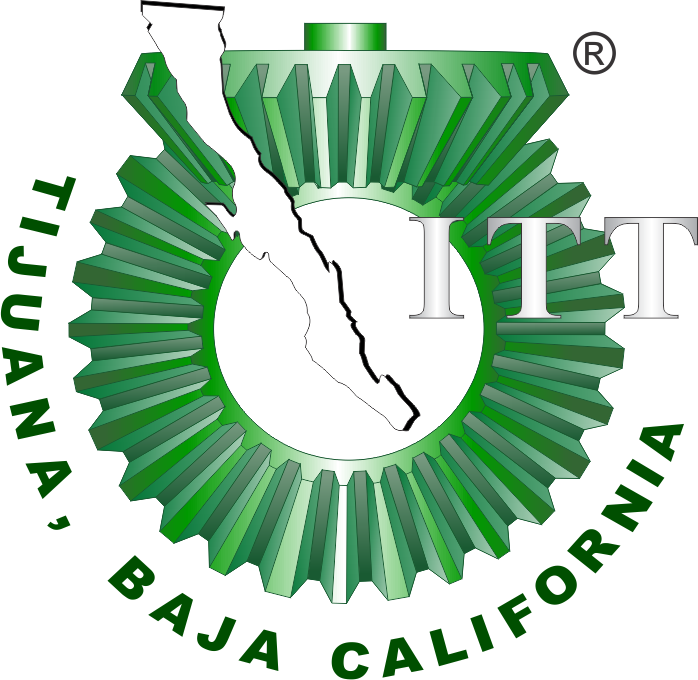

# Práctica 4: Modelado y control de sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

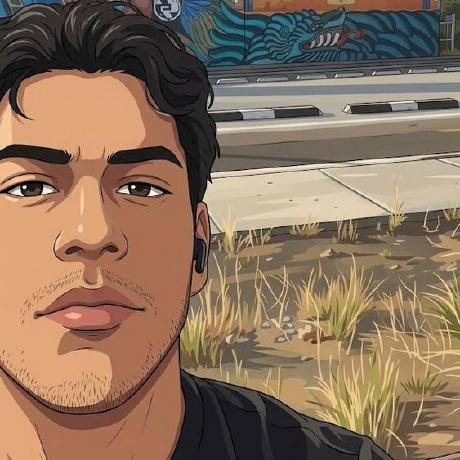

Nombre del alumno: Andrde Arellano Gael Sebastian

Número de control: 23212177

Correo institucional:** l23212177@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema1.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';


## Respuesta al impulso unitario

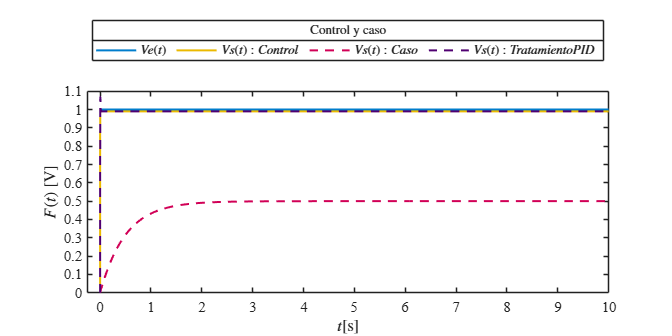

x1 = sim('sistema1.slx',parameters);
plotsignals(x1.t,x1.ve,x1.Vsx,x1.Vsy,x1.vsPID)

## Funcion: Respuesta a las señales

function plotsignals(t,c,c1,c2,c3)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;

ctrl1 = [0,125,204]/255;
ctrl2 = [235,185,0]/255;
ctrl3 = [209,0,86]/255;
ctrl4 = [80,0,113]/255;

order = [ctrl1;ctrl2;ctrl3;ctrl4];
colororder(order)

plot(t,c,'-',t,c1,'-',t,c2,'--',t,c3,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
    1:1e3:length(t));
L = legend('$Ve(t)$','$Vs(t): Control$','$Vs(t): Caso$', '$Vs(t):Tratamiento PID$');
set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
title(L,'Control y caso')
xlabel('$t$[s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')

xlim([-0.25 10]); xticks(0:1:10)
ylim([0 1.1]); yticks(0:0.1:1.1)
exportgraphics(gcf,'Control_caso_matlab4.pdf','contenttype','vector')
end
